# ECE 580 Make-Up Project

Yen-Chun Chen

934559635

clear; 
close all; 
clc; 
format compact; 

#### 1. Plot the pole Q (Qp) of the dominant pole of a fourth-order Chebyshev filter as a function of αp.

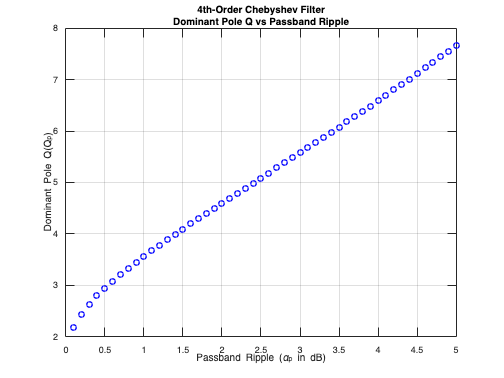

N = 4;                          
Wp = 2*pi*20e3;                 % cutoff frequency
alpha_p_values = 0.1:0.1:5;     % Range of passband ripple from 0.1dB to 5dB with step 0.1

Qp_values = zeros(size(alpha_p_values)); % Initialize array for Qp values with different passband ripples

for i = 1:length(alpha_p_values)

    Rp = alpha_p_values(i);
    
    [z, p, k] = cheby1(N, Rp, Wp, 'low', 's');
    
    % Calculate the Q factor for each pole
    Q_values = abs(p) ./ (2 * abs(real(p)));
    
    % Find the dominant pole
    Qp_values(i) = max(Q_values);

end

% Plot Qp as a function of alpha_p
figure;
plot(alpha_p_values, Qp_values, 'ob', 'LineWidth', 1.5);
xlabel('Passband Ripple (\alpha_p in dB)');
ylabel('Dominant Pole Q(Q_p)');
title({'4th-Order Chebyshev Filter','Dominant Pole Q vs Passband Ripple'});
grid on;

#### 2. Find the value of the largest passband ripple αp if the condition Qp < 5 must hold. Repeat for Qp < 3, Qp < 1.